# **Using MATLAB to realise clustering algorithms**

**黄骁 Huang Xiao (A0244823E)                                                                                        **

- 二维聚类

- 传统方法，采取kmeans

mu1=[0,0];
mu2=[0.5,0.5];
sigma=1

sigma = 1

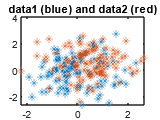

sigma1=[sigma,sigma];
data1=mvnrnd(mu1,sigma1,100);
data2=mvnrnd(mu2,sigma1,100);
plot(data1(:,1),data1(:,2),'*')
hold on
plot(data2(:,1),data2(:,2),'*')
title('data1 (blue) and data2 (red)')

dataset=[data1;data2];
y = chi2rnd(5,1500,1);    

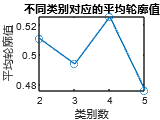

 
silh_method(dataset);

[~,y]=kmeans(dataset,2);
a=dataset(:,1);
[mu1,mu2]=p_method(a,sigma);
[mu3,mu4]=p_method(dataset(:,2),sigma);


 
%initialization of the result sets
DIYc1=[];
DIYc2=[];
DIYc3=[];
DIYc4=[];
DIYc5=[];
DIYc6=[];
kmeansc1=[];
kmeansc2=[];
h1=[];
h2=[];

 

for i=1:50
    [mu1,mu2]=p_method(a,sigma);
    [mu3,mu4]=p_method(dataset(:,2),sigma);
    DIYc1(end+1)=mu1;
    DIYc2(end+1)=mu3;
    %DIYc3(end+1)=a;
    %DIYc4(end+1)=b;
    %DIYc5(end+1)=c;
    %DIYc6(end+1)=d;
    kmeansc1(end+1)=mu2;
    kmeansc2(end+1)=mu4;
    c1=(DIYc1)';
    c2=(DIYc2)';
    %c3=(DIYc3)';
    %c4=(DIYc4)';
    %c5=(DIYc5)';
    %c6=(DIYc6)';
    kc1=(kmeansc1)';
    kc2=(kmeansc2)';
    result=[c1 c2 kc1 kc2];
end